## Strong Scaling Speedup/Efficiency

Using an exponentially increasing number of processors from 1 to 64 and a problem size of 2^28, a total of 7 tests were run that will be analzyed here. Below the plots for speedup and efficiency are generated.

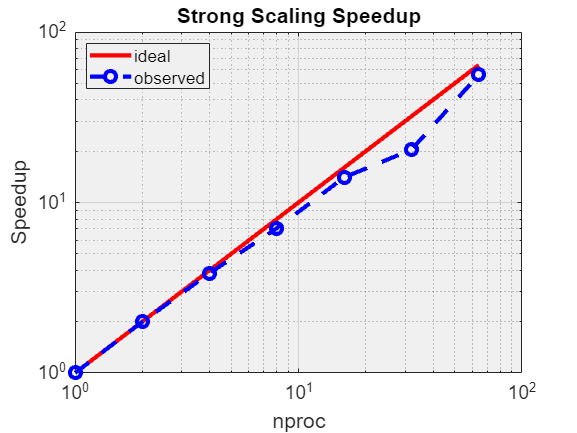

%Reading data
speedData=readmatrix('strongScaling1.csv');
nproc=speedData(:,1);
time=speedData(:,2);

speedup = time(1)./time;
idealSpeedup = nproc;

%Speedup
loglog(nproc,idealSpeedup,'r-',nproc,speedup,'bo--','LineWidth',3,'MarkerSize',8);
grid on;
xlabel('nproc','FontSize',14);
ylabel('Speedup','FontSize',14);
set(gca,'FontSize',14);
set(gca,'color',1/255*[240 240 240])
title('Strong Scaling Speedup');
legend('ideal','observed','Location','northwest');

The red solid line is the ideal linear speedup line. The dotted blue line is the observed speedup. The correlation is extremely strong up to when the experiment hit 32 processors. The R2 compute cluster has 28 processors per node. Communication between processors slows down a parallel program, ensuring no program can truly be 100% linear in speedup. However, communication between *nodes *drastically impacts the speedup of a program, especially if all of the processors on a secondary node are not being used. At 32 processors there are by default 4 on a different node than the original 28. The drop in speedup can be entirely attributed to that. The swift regain in correlation can be seen as the program is using 64 processors across 3 nodes. 2 full nodes are in full effect with another using 8 processors out of it's 28. This means there is far less wasteful communication as in the 32 processor test. In conclusion, it would be more effective to use 28 processors instead of 32, and thus 56 instead of 64.

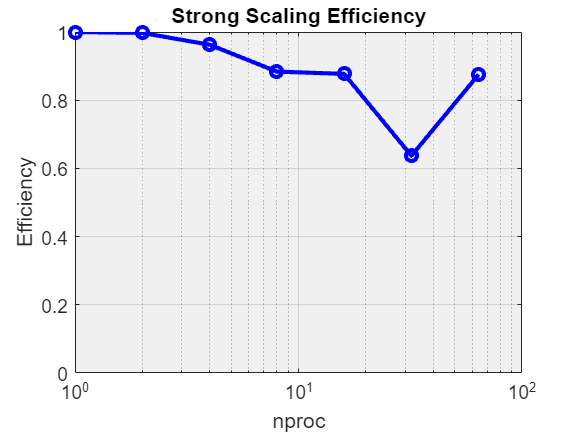

%Efficiency
E = speedup./nproc;
semilogx(nproc,E,'bo-','LineWidth',3,'MarkerSize',8);
grid on;
xlabel('nproc','FontSize',14);
ylabel('Efficiency','FontSize',14);
ylim([0 1]);
set(gca,'FontSize',14);
set(gca,'color',1/255*[240 240 240])
title('Strong Scaling Efficiency');

Perfect efficiency is impossible, but the goal is to come as close to 100% as possible. The program was highly efficient in the first 5 tests until, as seen in the speedup plot, there is a major dropoff at 32 processors. As previously noted, communication between nodes severely impacts a programs speedup and efficiency. The same bounce-back can be observed with the 64 processor test here, as more processors are being put to work with less communication between nodes required. 